% Import necessary packages
import matlab.net.http.*
import matlab.net.http.field.*

% Import deep learning layers and functions
import nnet.internal.cnn.layer.*
import nnet.internal.cnn.util.*
import nnet.internal.cnn.layer.util.*
import nnet.internal.cnn.sequence.*

maxEpochs = 10;
slice = 512-1;
rng("default")

ds = load('LabledData\raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;
dir = ds.Properties.RowNames;


Ds = {};
for i = 1:numel(dir)    
    raw_data = csvread(dir{i},1,1);
    filtered_data = hl_filter(raw_data(:,1),true);
    lable = lables(i);
    masked = getmask({filtered_data,lable{1,1}});
    Ds{i} = masked;  
end

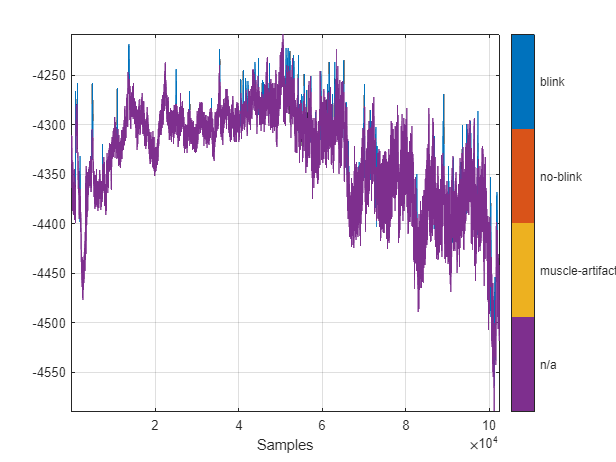

i=31;
classifyCategories = categorical({'blink','no-blink','muscle-artifact','n/a'});
figure
M = signalMask(Ds{i}{2});
raw_data = csvread(dir{i},1,1);

filteredDs = raw_data(:,1);
plotsigroi(M,filteredDs);


chopedDs = {};

for i = 1:numel(Ds)
    for j = 1:slice:numel(Ds{i}{1})-slice
        chopedDs{end+1} = {Ds{i}{1}(j:j+slice).',Ds{i}{2}(j:j+slice).'};    
%%%%%%%%%%%find weied data point
%         if numel(chopedDs) == 194
%             disp(i);
%         end

    end
end

XTrain = {};
YTrain = {};

for i = 1:numel(chopedDs)
    XTrain{end+1} = chopedDs{i}{1};
    YTrain{end+1} = chopedDs{i}{2};
end
XTrain;
YTrain;
[trainIdx,~,testIdx] = dividerand(numel(XTrain),0.7,0,0.3);

XTest = XTrain(testIdx);
YTest = YTrain(testIdx);
XTrain = XTrain(trainIdx);
YTrain = YTrain(trainIdx);
trainDs={};testDs={};
for i = 1:numel(XTrain)
    trainDs{end+1} = [{XTrain{i}},{YTrain{i}}];

end
for i = 1:numel(XTest)
    testDs{end+1} = [{XTest{i}},{YTest{i}}];
end


inputSeqLength = 512;
outputSeqLength = 512;
vocabSize = 10000; % You can adjust this according to the number of categories you have
numHeads = 8;
numLayers = 6;
modelDim = 64;
ffDim = 2048;
dropout = 0.1;
layers = [
    % Input layer
    sequenceInputLayer(inputSeqLength, 'Name', 'input')
    
    % Embedding layer
    wordEmbeddingLayer(modelDim, vocabSize, 'Name', 'embedding')
    
    % Positional encoding
    positionEncodingLayer('Name', 'position_encoding')
];

Unrecognized function or variable 'positionEncodingLayer'.


% Add transformer blocks
for i = 1:numLayers
    blockName = sprintf('transformer_block_%d', i);
    layers = [
        layers
        transformerLayer(numHeads, modelDim, ffDim, 'Name', blockName, 'Dropout', dropout)
    ];
end

% Add final layers
layers = [
    layers
    % Final normalization layer
    layerNormalizationLayer('Name', 'final_norm')
    
    % Output layer
    fullyConnectedLayer(vocabSize, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];


% Create the network
net = layerGraph(layers);
options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'GradientDecayFactor', 0.9, ...
    'SquaredGradientDecayFactor', 0.98, ...
    'Epsilon', 1e-9, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 64, ...
    'SequenceLength', 'longest', ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'gpu');



% Train the model (assuming inputSequences and targetSequences are already preprocessed)
net = trainNetwork(XTrain, YTrain, layers, options);

Error using trainNetwork
Invalid network.

Caused by:
    Layer 'attention_layer': Error using 'predict' in layer EncoderDecoderAttentionLayer. The function threw an error and could not be executed.
        Brace indexing is not supported for variables of this type.

        Error in EncoderDecoderAttentionLayer/predict (line 17)
                    encoderStates = X{1};

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end
Test = classify(tcnNet,TX,'MiniBatchSize',50);

TY = [];
Y = [];
for i = 1:numel(testDs)
    TY = [TY;testDs{i}{2}];
    Y = [Y;Test{i}];
end
figure
confusionchart(TY(:),Y(:),'Normalization','column-normalized','Title','TCN');

accuracy = accuracy_eval(Test, YTest)


n = 47;
for i = n:n+10
    number = i;
    Test = classify(tcnNet,XTest,'MiniBatchSize',50);
    Mtest = signalMask(testDs{number}{2}(1:5000));
    Mtest.SpecifySelectedCategories = true;
    Mtest.SelectedCategories = find(Mtest.Categories ~= "n/a");
    
    figure
    subplot(2,1,1)
    plotsigroi(Mtest,testDs{number}{1}(1:5000))
    title(i,'Ground Truth')
    
    Mpred = signalMask(Test{number}(1:5000));
    Mpred.SpecifySelectedCategories = true;
    Mpred.SelectedCategories = find(Mpred.Categories ~= "n/a");
    
    subplot(2,1,2)
    plotsigroi(Mpred,testDs{number}{1}(1:5000))
    title('Predicted')
end


i=194;
chopedDs{i}{1};

classifyCategories = categorical({'blink','no-blink','muscle-artifact','n/a'});
figure
M = signalMask(chopedDs{i}{2});
filteredDs = chopedDs{i}{1};
plotsigroi(M,filteredDs);
